# Developer documentation: `Delta`, `Performance`, and `Disturbance` objects

This documentation is targeted to developers who want to provide their own `Delta` and `MultiplierDelta` classes to further extend the expressive and analytical capabilities of `iqcToolbox`. The design structure for `Performance` and `Disturbance` classes is similar, and this documentation will also help developing those and related classes. After this script you will understand the architecture of `Delta` classes, the methods that must be implemented for a new `Delta` subclass, how `Delta` objects are grouped together in `SequenceDelta` classes, how a new `MultiplierDelta` subclass must interact with a new  `Delta` subclass, and any additional considerations for `Performance` and `Disturbance` classes.

## Motivation for abstract classes and inheritance

To begin, `iqcToolbox` is built with a heavy reliance on *object-oriented programming (OOP)*, which leverages classes and inheritance to structure software and implement various capabilities.  If you are unfamiliar with OOP and how MATLAB approaches OOP, two good places to start are [here](https://www.mathworks.com/help/matlab/object-oriented-programming.html) and [here](https://www.mathworks.com/help/matlab/matlab_oop/user-defined-classes.html).

*Note:*

*For developers familiar with OOP but unfamiliar MATLAB OOP: the typical OOP approach in MATLAB (and the approach followed in this toolbox) does not rely on references to objects. For example, syntax such as *`g_lft.addPerformance(...) `*does not modify the *`g_lft`* object, but outputs a new *`Ulft`* object with an added performance.*

In `iqcToolbox`, modeling and analysis is focused on a linear fractional transformation (LFT) of an uncertain and/or nonlinear system, annotated $(M, \Delta)$.

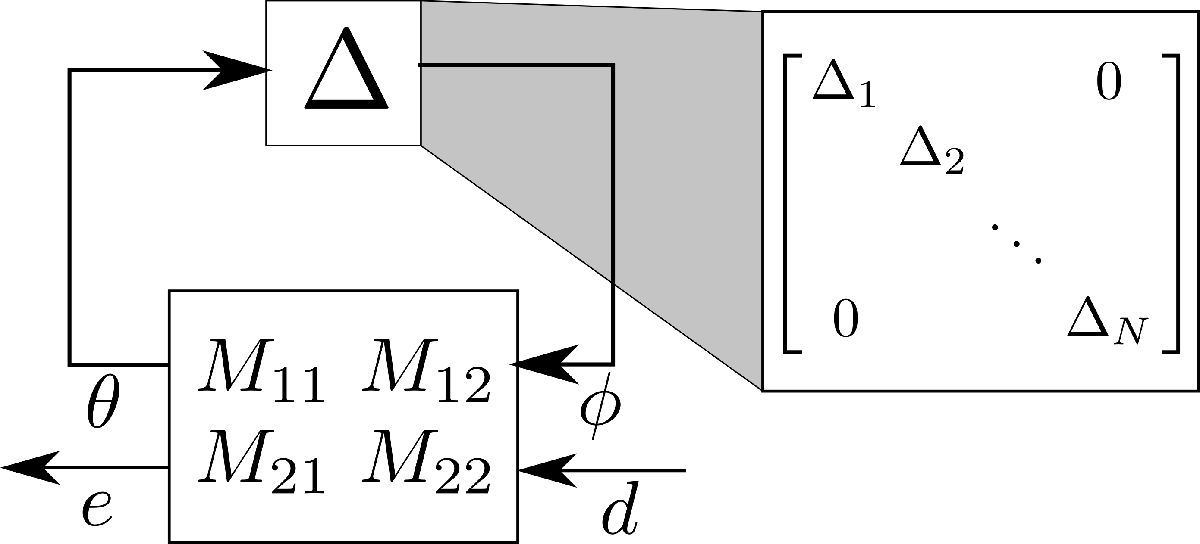

Typically, $\Delta$ represents a collection of different uncertainties, nonlinearities, and operators, which are structured together in a block-diagonal form: $\Delta = \mathrm{diag}(\Delta_1,  \Delta_2, ..., \Delta_N)$. For example, $\Delta_1$ might represent an uncertain parameter (such as mass) in the system's equations of motion, $\Delta_2$ might represent a nonlinear (but passive) friction force acting on the system, and so on. We see this structure in our `Ulft `class:

rng(4)
g_del = Ulft.random('num_deltas', 4)

Here we see a variety of different $\Delta$ objects: a dynamic linear time-invariant (DLTI) uncertainty, a static linear time-varying rate-bounded (SLTV-RB) uncertainty, an arbitrarily fast SLTV uncertainty, and so on. In order to allow a broad expression of different $\Delta$ sets in this toolbox (many of which may not be currently implemented or discovered), we structure each type of uncertainty/nonlinearity as a subclass of the abstract `Delta `class:

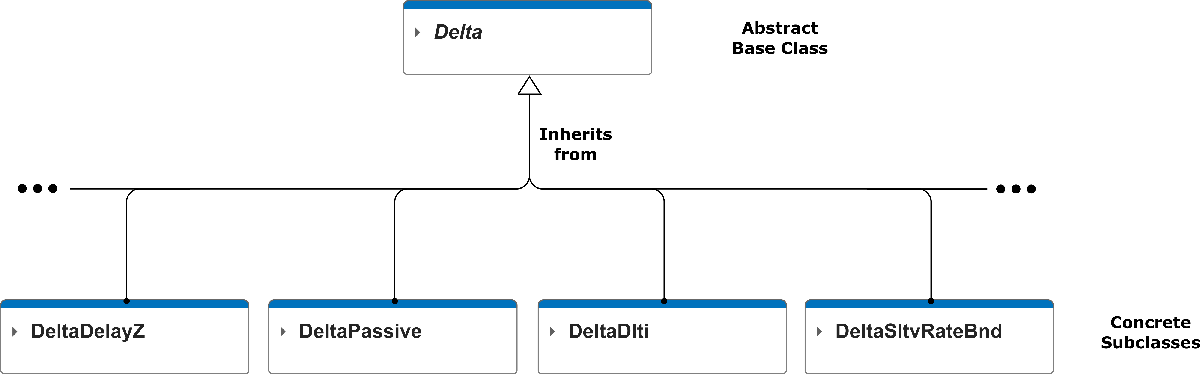

An abstract class cannot be instantiated:

% del = Delta('base_object', 1, 1, [0, 1]) % This will error because Delta is an abstract class

The purpose of the abstract `Delta` class is to provide the necessary properties and methods that all `Delta` subclasses will inherit, as well as force developers to concretize specific abstract methods which will be uniquely resolved by each subclass.  This allows the generation of novel subclasses while ensuring that each subclass has certain essential properties and methods that other classes (such as `Ulft)` and functions (such as `iqcAnalysis`) rely on.

There are numerous other abstract classes in `iqcToolbox` ( `MultiplierDelta`, `Performance`, `Disturbance`, etc.). This documentation will first focus on the `Delta` class, and then turn to the `MultiplierDelta` class.  Many of the same considerations of these two classes will apply for `Performance`, `MultiplierPerformance`, `Disturbance`, and `MultiplierDisturbance` classes. The following sections are intended to discuss the elements a developer should be aware of when developing a new `Delta` subclass, and similar observations can be made for `Performance` and `Disturbance` classes.

## Abstract `Delta` base class

As discussed in the previous section, every uncertainty/nonlinearity in `iqcToolbox` is a subclass of the abstract `Delta` class.  Here we discuss the properties and methods inherited from the `Delta` class, with particular attention on the base methods that *must* be overridden or concretized and the base methods that *may* be overridden.  The following graphic depicts how some `Delta` subclasses have extended the `Delta` class:

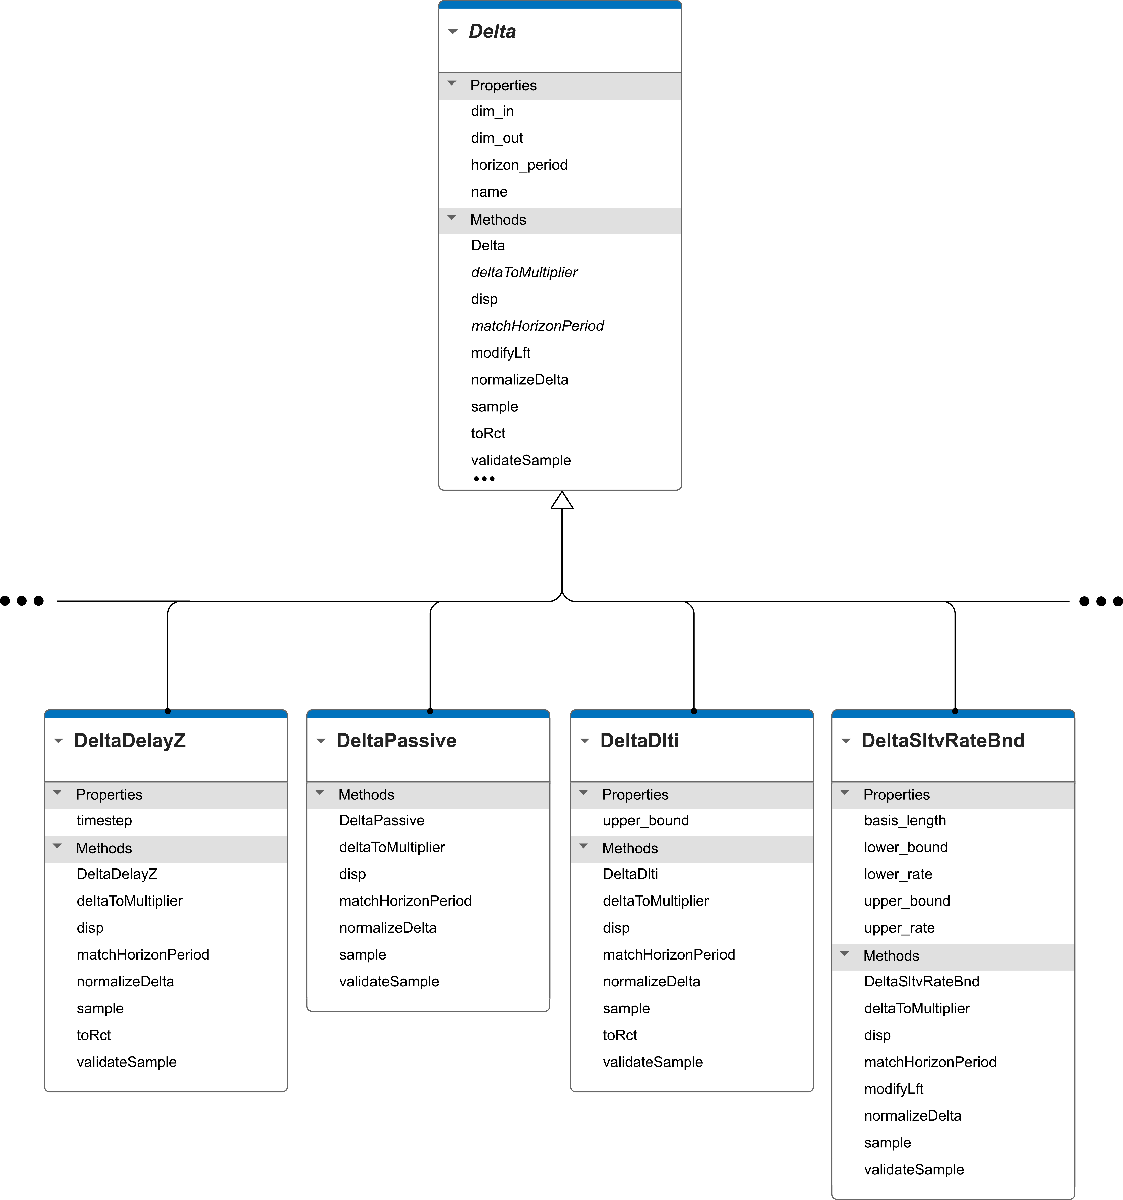

For example, `DeltaPassive` needs no additional properties beyond those from `Delta`. Such is not the case for any of the other listed subclasses.  Certain subclasses (`DeltaDelayZ` and `DeltaDlti)` override the `Delta.toRct` method, while others (`DeltaPassive` and `DeltaSltvRateBnd`) do not.

### Properties

#### `dim_out` and `dim_in`

These two properties are self-explanatory. They specify the input/output dimensions of the `Delta` object.

#### name

The unique identifier of this `Delta` object.  

del_mass = DeltaSlti('mass');
del_mass.name

Not only does this provide an identifier to users, it helps `Delta` "collectors" (formally, the `SequenceDelta` class) find and gather different appearances of the same `Delta` object into one term.

1 + del_mass
1 + del_mass * del_mass

Observe that in the last expression `del_mass` appeared twice but was listed only once as a `2 x 2` uncertainty in the resulting LFT. This is made possible by searching for all uncertainties that share the same `name` and gathering them together.

Such gathering can only occur if each same-named `Delta` is truly the same.

dim_outin = 1;
bnd1 = 1;
bnd2 = 2;
del_mass1 = DeltaSlti('mass', dim_outin, -bnd1, bnd1)
del_mass2 = DeltaSlti('mass', dim_outin, -bnd2, bnd2) % Same name, but different properties
% del_mass1 + del_mass2 % This will error because del_mass1 and del_mass2 have the same name but different properties

Hence, the `name` property not only provides an identifier to users, but helps the backend appropriately group uncertainties.

#### `horizon_period`

If you are unfamiliar with the `horizon_period` property, see the `horizon_period` subsection in the "Modeling uncertain systems with the Ulft class" documentation.  

It's important to note that this field only expresses the `horizon_period` of properties that define the related *multiplier* for this uncertainty/nonlinearity.  It does NOT specify that the $\Delta$ operator itself is eventually periodic with the given `horizon_period`. For example, a `DeltaSltv` object might have a `horizon_period` of `[2, 3]`, because its upper bound has the following pattern:


$$\texttt{upper\_bound}: \matrix{&\mathrm{period}:3&\mathrm{period}:3& \ldots \cr
[ \underbrace{1, \ 2},  &  \overbrace{3, \ 3, \ 4}, & \overbrace{3, \ 3, \ 4}, & \ldots] \cr
\mathrm{horizon}:2&&&}$$


which could be leveraged in constructing a $(2, \ 3)$-eventually periodic IQC multiplier. However, the uncertainty represented by `DeltaSltv` is not necessarily $(2, \ 3)$-eventually periodic; the uncertainty may vary arbitrarily over each timestep as long it remains within its eventually-periodic bounds.

#### A note on introducing new properties for subclasses

When designing a new `Delta` subclass, any properties needed to describe the uncertainty/nonlinearity may be introduced.  Three guiding principles to consider:

First, **only the properties necessary to construct the related multiplier should be defined**. This helps users know which properties are definitive for the uncertainty/nonlinearity.

Second, **do not include properties that describe the related multiplier but do not describe the uncertainty/nonlinearity**.  For example, `DeltaDlti` has only the additional property `upper_bound`. Its related multiplier `MultiplierDlti `has many other properties (`basis_poles`, `basis_length`, etc.), which are descriptive of how `MultiplierDlti` characterizes `DeltaDlti`. New `Delta` subclasses should follow the same separation of information.

Third, **any properties which depend on other properties should be implemented as "dependent" properties**. For example, `DeltaSltvRepeated` may describe different admissible regions for a collection of different uncertain parameters. These regions could be described with boxes, or with vertices, or with ellipses.  The region data for all of these types is in the property `region_data`, while ellipse descriptions that parse that data for ellipses is found in the "dependent" property `ellipses`.  Following this structure keeps users from inadvertently providing conflicting information when multiple properties can both be specified and describe each other.

### Methods

As of v0.9.0, the abstract `Delta` class has 23 methods. Two must be overridden, two must be concretized, five may be overridden, and fourteen cannot be overridden.  Fortunately, MATLAB OOP error handling helps developers know what methods they must implement and what they cannot implement.

#### Methods that must be overridden by subclasses

The following two methods must be overriden by any `Delta` subclass. Notably, each method, when overridden, ought to call the `Delta` base class's original method.

`Constructor`** (**`Delta(...))`

The constructor method for each subclass must be provided. Every `Delta` subclass constructor follows the same procedure:

- Input arguments are processed according to `nargin`, filling in defaults as necessary

- The base `Delta` class constructor is called: `this_delta@Delta(name, dim_out, dim_in, horizon_period)`

- Values of the subclass's extended properties are checked for consistency (for example, `lower_bound <= upper_bound` for subclasses that have both properties)

- Extended properties are set with the validated values

The base class constructor is called in order to avoid repeating validity checks for properties that are common across all `Delta` subclasses.

`disp(this_del)`

Without overriding this method, MATLAB will error when trying to display the subclass object to the user. The established procedure of this method should:

- Call the base method with a description of the subclass's type: `disp@Delta(this_delta, 'one line type description')`

- Print any additional information specific to this instance of the subclass (lower/upper bounds, etc.)

#### Abstract methods that must be concretized in subclasses

The following two methods are designated in the `Delta` base class as "abstract methods" (that is, methods without any implementation). Any subclass must implement these abstract methods in order for that subclass to be "concrete" (i.e., may be instantiated with a specific object).

`matchHorizonPeriod(this_del, new_horizon_period)`

This method is essential for ensuring each aspect of an LFT (its nominal system matrices, uncertainties/nonlinearities, disturbances, and perfomance) all have the same `horizon_period`. This method is also used to synchronize the `horizon_period` of two objects that have mismatching `horizon_period`, enabling operations between the two objects. For example:

dim_outin = 1;
hp1 = [1, 3];
del1 = DeltaPassive('del1', dim_outin, hp1);
hp2 = [2, 5];
del2 = DeltaPassive('del2', dim_outin, hp2);
del_sum = del1 + del2
del_sum.horizon_period

The ability to produce an object that has a `horizon_period` consistent with the `horizon_period` of each constituent element depends on an implementation of `matchHorizonPeriod` for each constituent object.

For this method, the only consideration developers must address when implementing new `Delta` subclasses are the subclass's properties that rely on the `horizon_period`.  These are typically properties such as `dim_out`, `dim_in`, `upper_bound`, and so forth. Developers can find examples of `matchHorizonPeriod` in existing subclasses, but the generic procedure for the method is as follows:

- Get indices and `horizon_period` that are consistent with the current `horizon_period` and the desired `horizon_period `(e.g. `[indices, new_hp] = makeNewIndices(current_hp, desired_hp))`

- Set `horizon_period`-dependent properties to be consistent with new `horizon_period` (e.g. `this_del.dim_out = this_del.dim_out(indices)`)

When `matchHorizonPeriod` is not provided with a `horizon_period` input, the method is being used to check that each `horizon_period`-dependent property of the object is consistent with its own `horizon_period`. This can be implemented with simple `assert()` statements. Examples abound in the various `Delta` subclasses.

`deltaToMultiplier(this_del, varargin)`

This method essentially constructs the associated `MultiplierDelta` subclass object from the given `Delta` subclass object. It requires having the `MultiplierDelta` subclass and its constructor defined, and is implemented very easily:

`multiplier = MultiplierDeltaSubclass(this_del, varargin)`

*Note:*

*While a successful implementation of this method requires that the *`MultiplierDelta`* subclass and its constructor are defined, the *`deltaToMultiplier`* method only becomes necessary when wanting to conduct IQC analysis. Hence, it may be advantageous to implement a dummy stub for the method first (such as: *`error('this is not implemented yet')`*) to first finish the other methods and test instantiations of the new *`Delta`* subclass interacting with the *`Ulft`* class and other *`Delta`* subclasses. Once the other methods are established, development can turn to the *`MultiplierDelta`* subclass, its constructor, and calling that constructor in the *`deltaToMultiplier`* method.*

#### Methods that may be overridden by subclasses

These five methods are convenience methods that broaden the capabilities of `Delta` subclass objects.  Not all of them can be implemented for every `Delta` subclass, and the base class implementation essentially does nothing or throws a "not implemented" error. Developers may override any of these methods, but it's not necessary for allowing their `Delta` subclass to access basic IQC analysis.

`modifyLft(this_delta)`

This method is only necessary for `Delta` subclasses that require modifying the containing LFT in order to conduct IQC analysis. A demonstration of this use case can be found in the `DeltaSltvRateBnd` and `DeltaSltvRateBndImpl` classes, where objects from the former class transform the parent LFT to have different [`a, c]` matrices and a `DeltaSltvRateBndImpl` object. A similar use case for the `Performance` class can be found in the `PerformanceStable` subclass.

This method is typically not used, and a developer would know by the nature of their uncertainty/nonlinearity if they needed to override the base method. The base `Delta` implementation returns an empty function handle to indicate that no modifications of the LFT need to occur.

`normalizeDelta(this_delta)`

This method is used to normalize bounds of `Delta` subclass objects that have `upper_bound` or `upper_bound`/`lower_bound` properties, such that the normalized `Delta` subclass objects have `upper_bound = 1` (and `lower_bound = -1` for objects that have a `lower_bound` property). The method returns transformation parameters that are used to modify the `a`, `b`, `c` matrices of a parent LFT such that an equivalent LFT can be represented with the normalized `Delta` subclass objects.

This method is only meaningful to `Delta` subclasses that have an `upper_bound` property (see, for example, `DeltaBounded` or `DeltaDlti`) or an `upper_bound` and `lower_bound` property (see, for example, `DeltaSlti` or `DeltaSltv`). The base `Delta` implementation returns values which indicate that no normalization was performed and throws a warning flag that no normalization occurred for the `Delta` object.

`toRct(this_delta)`

This method is used to transform a given `Delta` subclass object into an uncertainty object in the Robust Control Toolbox package. Given the comparatively limited scope of uncertainties that can be treated in the Robust Control Toolbox, `toRct` can only be overridden by `DeltaSlti` and `DeltaDlti` classes. All other uncertainties/nonlinearities represented as `Delta` subclasses rely on the base `Delta` class implementation: create a placeholder `udyn` object with the same name as that from the `Delta` subclass object. However, in case of unforeseen changes in Robust Control Toolbox, this method may be overridden in future `Delta` subclasses.

`sample(this_delta, timestep)`

This method randomly samples a system that satisfies the characteristics of the uncertainty/nonlinearity set described by `this_delta`. The sample is a state-space system expressed as a `Ulft` object, so for many `Delta` subclass objects (especially ones specifying nonlinearities) the permissible sample set will not widely cover the set described by `this_delta`. In some cases, this method will not be able to return any state-space system that resides in the set described by `this_delta`. The base `Delta` class implementation simply throws an error saying that this method has not been developed for the `Delta` subclass.

The `timestep` parameter describes if `this_delta` is an operator in continuous or discrete time.  For example, an uncertain delay can have a state-space representation in discrete time, but not in continuous time. See `DeltaConstantDelay2` and `DeltaSltv` for examples of `sample()` that do and do not rely on the `timestep` parameter (respectively).

`validateSample(this_delta, value, timestep)`

This method takes a state-space system `value` (expressed as a `Ulft` object) and determines if it lies within the set described by `this_delta`. The base `Delta` class implementation checks that the properties of `value` are consistent with the properties of the base `Delta` class. This can be extended in each subclass, and it is suggested that any overridding method calls that base method. Similar to the `sample()` method, `validateSample()` will need the `Ulft.timestep` information for certain `Delta` subclasses.

#### Methods that may not be overridden by subclasses

The remaining methods of the `Delta` class are not allowed to be overridden.  They allow MATLAB to treat any `Delta` object as a `Ulft` object for various operations (addition, multiplication, etc.).  They should be of no concern to the developer.

## `SequenceDelta` class

As discussed at the beginning of this documentation, an LFT has at least one, usually many, different types of uncertainties/nonlinearities that are structured block diagonally to represent the $\Delta$ block. The `SequenceDelta` class provides consistency checking and basic backend management of the various `Delta` objects that represent the different uncertainties, nonlinearities and operators in $\Delta$. 

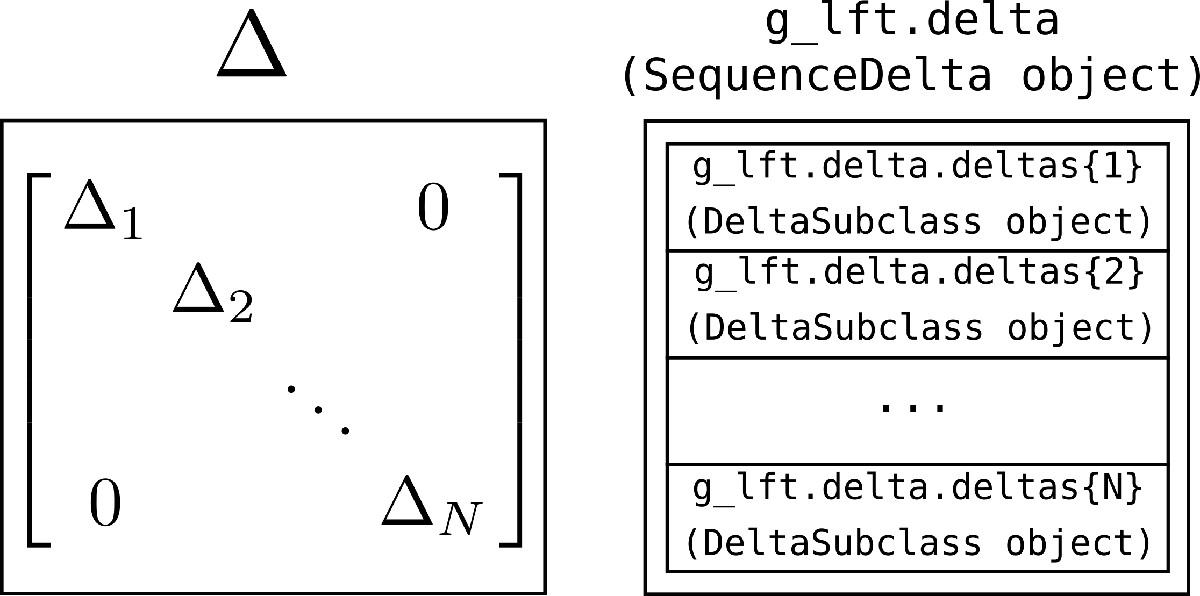

Consider the `SequenceDelta` class as a glorified cell array class that provides convenient handles and basic processing for each element in its array. It should mostly be invisible to the user, and is only discussed here to preempt any questions from the developer.

Any `Ulft` object contains a `SequenceDelta` object, which contains all the `Delta` objects for the LFT:

g_lft = Ulft.random('num_deltas', 4)
class(g_lft.delta)
g_lft.delta
properties(g_lft.delta)
g_lft.delta.deltas{1}

The central property of a `SequenceDelta` object is `deltas`, a standard cell array of `Delta` objects.  All other properties (`names`, `types`, `dim_outs`, etc.) are for convenience and depend on the `deltas` property. The `SequenceDelta` object also makes basic consistency checks among `Delta` objects in its cell array.

integrator = DeltaIntegrator; % continuous-time state evolution operator
delay = DeltaDelayZ; % discrete-time state evolution operator
% SequenceDelta(integrator, delay) % this will error, cannot combine discrete-time with continuous-time elements

Developers should not be concerned with modifying this class.

## `MultiplierDelta` classes

In `iqcToolbox`, the modeling aspects and the analysis aspects are separated.  One can model an uncertain/nonlinear system with a `Ulft` object that contains various `Delta` objects, and then easily manipulate/inspect/sample that system. However, `Delta` classes are not sufficient for conducting IQC *analysis* on the system.  The ability to leverage IQCs for an uncertain system depends on `MultiplierDelta` classes, which express how such `Delta` classes can be characterized for IQC analysis. In other words, `Delta` classes provide all the information to describe an uncertainty/nonlinearity set, while `MultiplierDelta` classes describe how that set will be characterized in a robustness analysis framework.

The connection between these two classes exists in the `Delta.deltaToMultiplier` method and the `MultiplierDelta` constructor method, each of which must be defined by the developer:

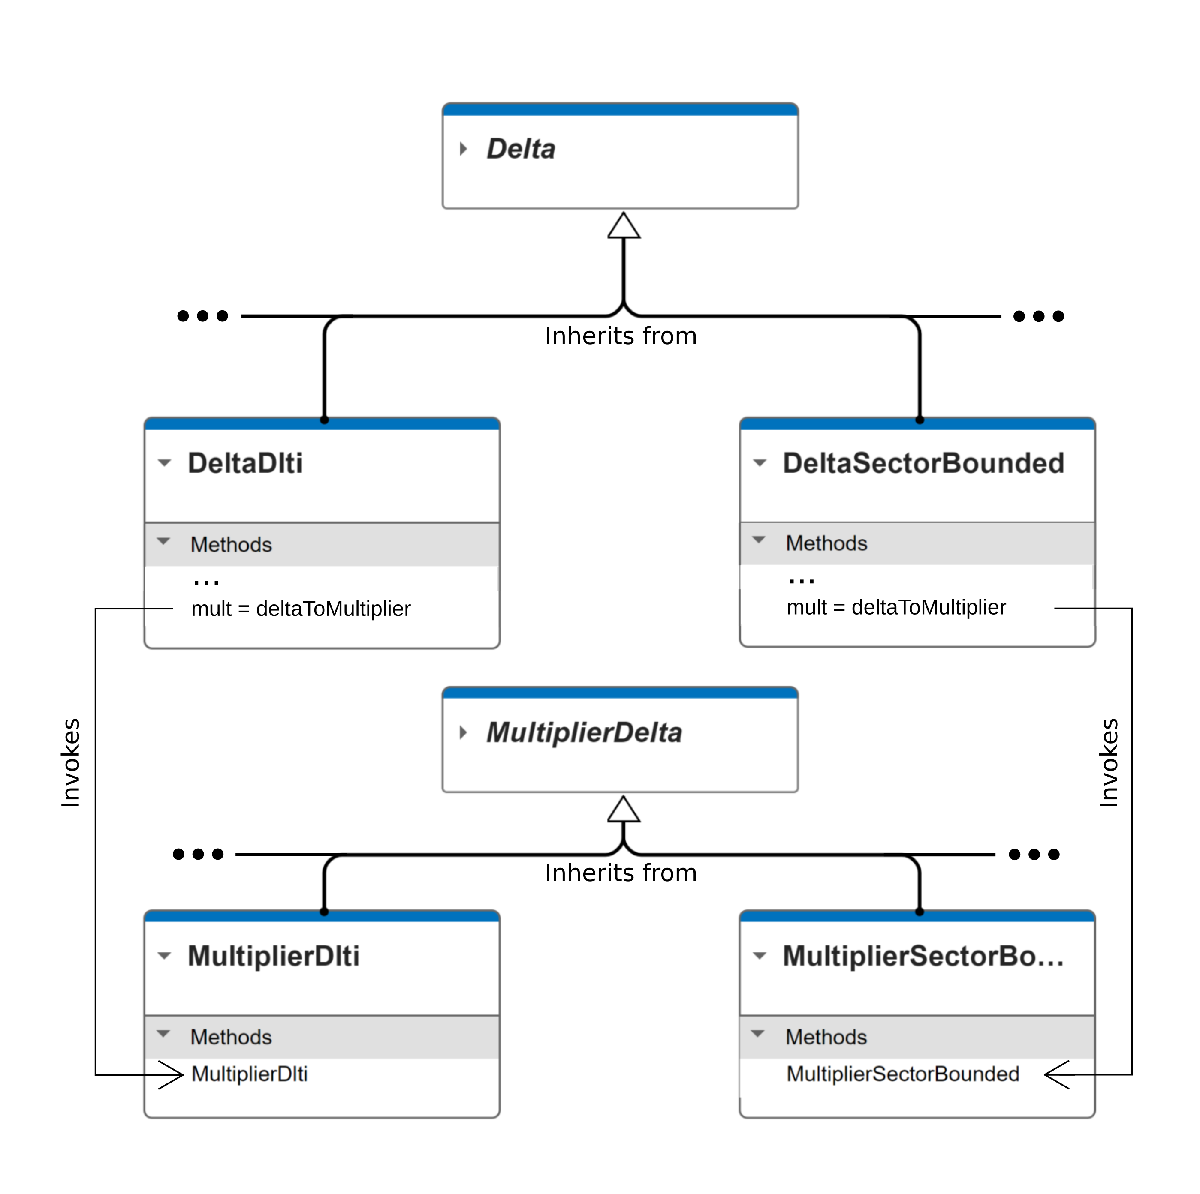

This section provides considerations for a developer when implementing a `MultiplierDelta` subclass to enable IQC analysis that can incorporate their newly implemented `Delta` subclass.

### A brief theoretical description of IQC multipliers

An IQC multiplier $\Pi$ is a bounded, linear, self-adjoint operator on $\ell_2$. In this toolbox, we only treat IQC multipliers that have a state-space representation. An uncertainty or nonlinearity $\Delta$ is said to satisfy the IQC defined by $\Pi$ (annotated $\Delta \in \mathrm{IQC}(\Pi)$) if


$$(1) \qquad \langle \left[\matrix{\theta \cr \phi}\right], \Pi \left[\matrix{\theta \cr \phi}\right]\rangle\geq 0 \ \mbox{ for all } \theta \in \ell_2, \ \mbox{ with } \phi = \Delta(\theta)$$


where $\langle \cdot, \cdot \rangle$denotes the inner-product on $\ell_2$.

An IQC multiplier $\Pi$ can be factorized as $\Pi = \Psi^* S \Psi$, where $\Psi$represents a stable (possible time-varying) state-space filter, and $S$ is a symmetric matrix.  In the `MultiplierDelta` class, the property `filter` refers to $\Psi$, and the property `quad` refers to $S$. 

In order to ensure a `Delta` subclass object satisfies (1), the pertinent `MultiplierDelta` subclass must structure its `filter` and `quad` appropriately and put `Delta`-informed constraints on `quad`. The developer must know what those structures and constraints would be for their given `Delta` subclass. The abstract `MultiplierDelta` class provides the necessary properties that any IQC multiplier must have in order to leverage IQC analysis for their `Delta` subclass.

### Abstract `MultiplierDelta` base class

Similar to the abstract `Delta` base class, the abstract `MultiplierDelta` base class provides a foundation for developers to implement their own `MultiplierDelta` subclass. Unlike the `Delta` class, developers only need to be concerned with implementing constructor methods for their `MultiplierDelta` subclass.  No other methods are needed to create a concrete `MultiplierDelta` subclass. It is possible (but not necessary) that developers will introduce new properties in their `MultiplierDelta` subclass that gives users the freedom to expand or limit the richness of an instance of the `MultiplierDelta` class (see the "Conducting IQC analysis" documentation to better understand why and how users control the expressiveness of a specific `MultiplierDelta` instance).

#### Properties

`name`

This property provides a unique identifier to the multiplier.  It should be the same value as that of the `Delta` object it describes:

d = DeltaSlti('del1');
m = MultiplierSlti(d);
d.name 
m.name

`filter`

Given an IQC multiplier $\Pi$, which is represented by a `MultiplierDelta` object `mult`, a factorization $\Pi = \Psi^* S \Psi$ is represented by `mult.filter' * mult.quad * mult.filter`. In other words, `filter` represents the filter portion of a factorization of an IQC multiplier.

`filter` is a structure that has fields `a`, `b1`, `b2`, `c1`, `c2`, `d11`, `d12`, `d21`, `d21`, each of which are cell arrays describing the (possibly time-varying) state-space matrices of `filter`. Even if `filter` will always be a time-invariant system, it is important (for consistency) that each of the aforementioned fields for state-space matrices are cell arrays.

The `filter` property state-space matrices are broken into 2 x 2 blocks in order to enable the backend combination of different multipliers into a single multiplier.

For convenience, the state-space representation described by `filter` can be generated as a `Ulft` object with the dependent property `filter_lft`

`quad`

The `quad` property represents $S$ in the factorization $\Pi = \Psi^* S \Psi$. It is a structure that has fields `q11`, `q12`, `q21`, `q22`, all of which are cell arrays to describe the (possibly time-varying) matrices that describe $S$. Similar to `filter`, it is broken in 2 x 2 blocks to enable the backend combination of different multipliers into a single multiplier.

Whereas the property `filter` has numeric matrices describing its fields, `quad` is typically  composed of doubles and decision variables, the latter type being represented by `sdpvar` objects from the YALMIP toolbox [1]. These decision variables are constrained in some manner so that $\Delta \in \mathrm{IQC}(\Psi^* S \Psi)$

m.quad.q11{1}

When defining `quad` in the constructor, because `quad` must represent a sequence of symmetric matrices, `q12{i}` must equal `q21{i}'`.

`decision_vars`

This property is a cell array containing all the decision variables that help compose the multiplier. In this toolbox, decision variables are represented by `sdpvar` objects.

While the elements in the `decision_vars` array are not needed after they have been constrained, this field is provided for users to inspect the attained values after `iqcAnalysis` has been called and an optimization routine provides values for those variables.

m.decision_vars{1}

`constraints`

The `constraint` property is an `lmi` object (from YALMIP) that describes the constraints placed on the decision variables of a `MultiplierDelta` subclass object.  It must be defined during the `MultiplierDelta` subclass's constructor method. These constraints will be included later with additional constraints generated in the `iqcAnalysis` function in order to formulate the IQC analysis semidefinite program.

m.constraints(1)

When creating constraints in the constructor, it is recommended (but not necessary) to add a tag to the constraint, for ease of reference.

`horizon_period`

This property reflects the `horizon_period` of the multiplier.  It must be the same as the `horizon_period` of the associated `Delta` subclass object.

d.horizon_period
m.horizon_period

`discrete`

This property describes if the multiplier is operating on the discrete-time signal space $\ell_2$ or the continuous-time signal space $\mathcal{L}_2$. This property is only used when `filter` has dynamics (i.e., the `a` matrices are not empty). The default assumption is that a multiplier is a discrete-time system, even if the multiplier is memoryless.  See `MultiplierSlti` and `MultiplierSltv` for examples of `MultiplierDelta` subclasses that respectively use and that do not use the `discrete` property.

Importantly, `discrete` is not a property of a `Delta` subclass object, which typically can be specified for either discrete-time *or* continuous-time systems.  Rather, a multiplier will be determined to be discrete- or continuous-time if the LFT containing the multiplier's associated `Delta` object is discrete- or -continuous-time (i.e., the `Ulft` object also has a `DeltaDelayZ` or `DeltaIntegrator` object).

`filter_lft`

As mentioned in the `filter` property, this property is a dependent "convience" property that parses `filter` into a `Ulft` object that can be easily inspected and manipulated.

m.filter_lft

`exponential`

This field describes the exponential rate specified by an IQC multiplier.  Developers can turn to the "Exponential IQCs" documentation for more information on exponential convergence analysis.

#### Methods

When developing a `Delta` sublcass, four methods must be implemented or overridden. However, with `MultiplierDelta` subclasses, developers need only implement their `MultiplierDelta` subclass constructor.

**A note on providing expressive flexibility for multipliers**

It is important to recognize that a `MultiplierDelta` subclass will have decision variables that are appropriately constrained to characterize its related `Delta` subclass. Hence a `MultiplierDelta` subclass object does not usually have a pre-determined value; until the multiplier's decision variables are determined by an semidefinite program solver, a single `MultiplierDelta` subclass object represents a set of IQC multipliers. As discussed in the "Conducting IQC analysis" documentation, the breadth of the feasible set of IQC multipliers expressed by a `MultiplierDelta` subclass object should be flexibly determined by the user; in some cases a user will want the semidefinite program to have a larger space of decision variables (to reduce conservatism) or a smaller space of decision variables (to reduce the computational burden). For example, consider the static, linear, time-invariant uncertainty and different sets of multipliers that can characterize it:

del2 = DeltaSlti('del2', 2* dim_outin, -bnd2, bnd2)
m_simple = MultiplierSlti(del2, 'constraint_q11_kyp', false);
m_rich = MultiplierSlti(del2, 'constraint_q11_kyp', true);
m_simple.decision_vars{:}
m_rich.decision_vars{:}

Because the user specified the inclusion on a richer constraint for the latter multiplier, more decision variables are availble to express the set of feasible IQC multipliers pertaining to `del2`. We can also see this changes the types of constraints on those decision variables:

m_simple.constraints
m_rich.constraints

Developers can observe examples on how those different expressivity options are available to users in existing classes, such as `MultiplierSlti` (using parameters `constraint_q11_kyp` and `constraint_q12_kyp`) or `MultiplierSltv` (using parameters `quad_time_varying`). 

**A note on providing flexible parameterization of multipliers**

In addition to the previous note, it is useful to allow users to provide different parameterizations of multipliers. For example, although the `filter` property of a given `MultiplierDelta` subclass instance represents a deterministic state-space system, different instances of the subclass may have different expressions for the `filter` property.  These could be more richer, simpler, or just different `filter` systems.

m_filter1 = MultiplierSlti(d, 'basis_length', 2);
tf(lftToSs(m_filter1.filter_lft)) % filter printed as a ss system:
m_filter2 = MultiplierSlti(d, 'basis_length', 3);
tf(lftToSs(m_filter2.filter_lft)) % filter printed as a ss system:
another_basis = tf(drss(1, 1, 1));
m_filter3 = MultiplierSlti(d, 'basis_function', another_basis);
tf(lftToSs(m_filter3.filter_lft)) % filter printed as a ss system:

A well-developed `MultiplierDelta` will provide users with a means to flexibly define the parameterizations of these deterministic elements of an IQC multiplier.  Examples of this can be found in the `MultiplierConstantDelay2` and `MultiplierSlti` classes.

**Typical steps for **`MultiplierDelta`** subclass constructors**

Since IQC multipliers differ widely for various uncertainty/nonlinearity types, the `MultiplierDelta` subclass constructors also differ widely.  However, a standard process that every `MultiplierDelta` subclass constructor follows appears below:

- Parse inputs and assign basic properties of object (not including `filter`, `quad`, `decision_vars`, and `constraints`)

- Use assigned basic properties to generate and assign `filter`, `quad`, and `decision_vars`

- Set constraints on the generated decision variables

This process is somewhat loose; for some `MultiplierDelta` subclasses, one step will still be occurring when another begins.  But it provides the basic framework for developers to start with.  Obviously, examples from different subclasses will be instructive.

**1. Parsing inputs and assigning basic properties**

Unlike `Delta` subclasses, inputs for `MultiplierDelta` subclass constructors are parsed with MATLAB's [input parser framework](https://www.mathworks.com/help/matlab/matlab_prog/parse-function-inputs.html). This provides better flexibility to the user by having inputs specified with optional key/value pairs. There are two "optional" inputs that MUST be specified for every `MultiplierDelta` subclass constructor: the parameters `discrete` and `exponential`. A developer that is creating a `MultiplierDelta` subclass which isn't dependent  `discrete` or `exponential` should still insert the following code:

input_parser = inputParser;
% Placeholder code that should appear in all MultiplierDelta subclass constructors
addParameter(input_parser,... % This parameter is not used. Only defined for compatibility with other Multiplier constructor calls
             'discrete',...
             true,...
             @(disc) validateattributes(disc, {'logical'}, {'nonempty'}))
addParameter(input_parser,... % This parameter is not used. Only defined for compatibility with other Multiplier constructor calls
             'exponential',...
             [],...
             @(disc) validateattributes(disc, {'double'}, {'finite'})) 

These lines are important because other external functions will try to construct `MultiplierDelta` objects with these two arguments, regardless of the subclass.

**2. Generating and assigning **`filter`**, **`quad`**, and **`decision_vars`

These properties will depend on the nature of the `Delta` subclass this multiplier is characterizing.  Developers can find numerous examples of this construction from the existing `MultiplierDelta` subclasses. As an important note, `quad` must represent a sequence of symmetric matrices.  Hence, developers must ensure that `quad.q21{i} = quad.q12{i}'` for all `i`.

**3. Defining constraints on generated decision variables**

Sometimes these constraints are defined in step with `quad` and `decision_vars`.  Though not necessary, it is useful to add tags to every generated constraint:

X = sdpvar(2); % Dummy decision variable for following lines of code
constraint = []; % No constraints yet
constraint = constraint + [X >= 0]:'X >= 0 for [this_mult.name]'

#### **Arrays of **`MultiplierDelta`** objects**

`MultiplierDelta` subclass objects are collected differently than `Delta` subclass objects.  Whereas `Delta` objects are collected and managed with the `SequenceDelta` object, which is a container for `Delta` objects, `MultiplierDelta` objects actually inherit from a MATLAB-provided array class `matlab.mixin.Heterogeneous`. This allows `MultiplierDelta` objects to be treated more intuitively as arrays:

d_sltv = DeltaSltv('d_sltv');
sequence_of_deltas = SequenceDelta(d_sltv, del1, del2)
m_sltv = MultiplierSltv(d_sltv);
m_del1 = MultiplierPassive(del1);
m_del2 = MultiplierSlti(del2);
array_of_multipliers = [m_sltv, m_del1, m_del2]

The base method `MultiplierDelta.getDefaultScalarElement` is defined in order to automatically fill in undefined elements of an intialized array:

array2(3) = m_del2
array2(1)

Developers need not be concerned with the `getDefaultScalarElement` in their development efforts. 

## Considerations for `Performance` and `Disturba`n`ce` classes

While the previous sections focused solely on `Delta`, `SequenceDelta`, and `MultiplierDelta` classes, almost all of those discussions are applicable to `Performance`/`SequencePerformance`/`MultiplierPerformance`, and `Disturbance`/`SequenceDisturbance`/`MultiplierDisturbance` classes.  However, we make a few notes here that are specific to these two groups of classes.

### `dim_out, dim_in` versus `chan_out, chan_in`

Whereas the `Delta` class provides `dim_out` and `dim_in` properties, the `Performance` and `Disturbance` classes specify channels of an LFT's output/input signals instead. 

For `Performance` objects, this means that a performance metric can be defined across specific (possibly non-contiguous) channels of an LFT's output/input signals:

chan_out = {[1; 3]};
chan_in = {[4]};
perf = PerformanceL2Induced('l2', chan_out, chan_in)

For `Disturbance` objects, this means that a disturbance characterization can be defined for specific (possibly non-contiguous) channls of an LFT's input signal:

white = DisturbanceBandedWhite('white', chan_in)

When `chan_in` or `chan_out` is a cell array of empty doubles, this indicates that all channels are considered:

perf_all_chan_out = PerformanceL2Induced('l2', {[]}, chan_in)

Having this flexibility incurs one additional developer overhead in the `MultiplierPerformance` and `MultiplierDisturbance` subclass constructors: the multiplier must also depend on the associated LFT's output/input dimenstions.  This means the input parser must define `dim_in_lft` for both `MultiplierDisturbance` and `MultiplierPerformance` subclass constructors, and `dim_out_lft` for `MultiplierPerformance` subclass constructors. This also means the `performanceToMultiplier` and `disturbanceToMultiplier` methods in the `Performance` and `Disturbance` subclasses must pass those arguments on to the respective `MultiplierPerformance` and `MultiplierDisturbance` constructors. Examples of these design considerations can be found in existing `Performance`/`MultiplierPerformance` and `Disturbance`/`MultiplierDisturbance` classes.

### `MultiplierPerformance` considerations

The `MultiplierPerformance` class includes two additional properties that don't exist in the `MultiplierDelta` class: `objective` and `objective_scaling`.

The `objective` property will be defined differently for different subclasses.  For example, with the `PerformanceL2Induced` class, `objective` reflects the pre-determined value or the decision variable that expresses an upper bound on the square of the $\ell_2$-induced gain:

chan_out = {[]};
chan_in = {[]};
dim_out = 1;
dim_in = 1;
l2 = PerformanceL2Induced('l2_unknown', chan_out, chan_in); % Making the l2-induced gain a decision variable
m_l2 = MultiplierL2Induced(l2, dim_out, dim_in);
m_l2.objective
fixed_gain = 10;
l2 = PerformanceL2Induced('l2_fixed', chan_out, chan_in, fixed_gain);
m_l2 = MultiplierL2Induced(l2, dim_out, dim_in);
m_l2.objective

The `objective_scaling` property determines how much weight will be placed on the `mult.objective `for the semidefinite program.  This becomes meaningful when multiple objective values (such as `state_amplification`) are being optimized (see the "Conducting IQC analysis" documentation for more details and examples).

### `MultiplierDisturbance` considerations

The `MultiplierDisturbance` base class has no additional properties beyond the `MultiplierDelta` base class. However, the descriptions for a `MultiplierDisturbance` object's `filter` and `quad` are NOT divided into 2 x 2 blocks.

is_discrete = true;
chan_in = {[1]};
white = DisturbanceBandedWhite('white', chan_in);
mult_disturbance = MultiplierBandedWhite(white, dim_in, is_discrete);
mult_delta = MultiplierSlti(d);
mult_disturbance.quad % Only a q cell array for disturbance multipliers
mult_delta.quad % A q11, q12, q21, and q22 cell array for delta multipliers
mult_disturbance.filter % Only a, b, c, d arrays of state-space matrices for disturbance multipliers
mult_delta.filter % a, b1, b2, c1, c2, d11, d12, d21, d22 arrays of state-space matrices for delta multipliers

This deviation is driven by the theoretical difference of a $\Delta$ satisfying an IQC defined by $\Pi_\Delta$, and a disturbance set $\mathcal{D}$ satisfying an IQC defined by $\Pi_D$.

## Conclusion

Congratulations, you're now aware of the design considerations when developing novel `Delta`, `Disturbance`, and `Performance` classes for `iqcToolbox`! If you want to design `Delta` classes that leverage the notion of exponential IQCs, take some time reading through the "Exponential IQCs" documentation. If you want to dive right into developing a specific class, be sure you're familiar with the [contributing guidelines](https://github.com/iqcToolbox/iqcToolbox/blob/master/CONTRIBUTING.md) to know our approach for suggesting and merging in new features.

## `References`

[1] Lofberg, J. (2004, September). YALMIP: A toolbox for modeling and optimization in MATLAB. In *2004 IEEE international conference on robotics and automation (IEEE Cat. No. 04CH37508)* (pp. 284-289). IEEE.